# 仿真数据后处理

## 读取数据

clear;
clc;

#### 剖面数据

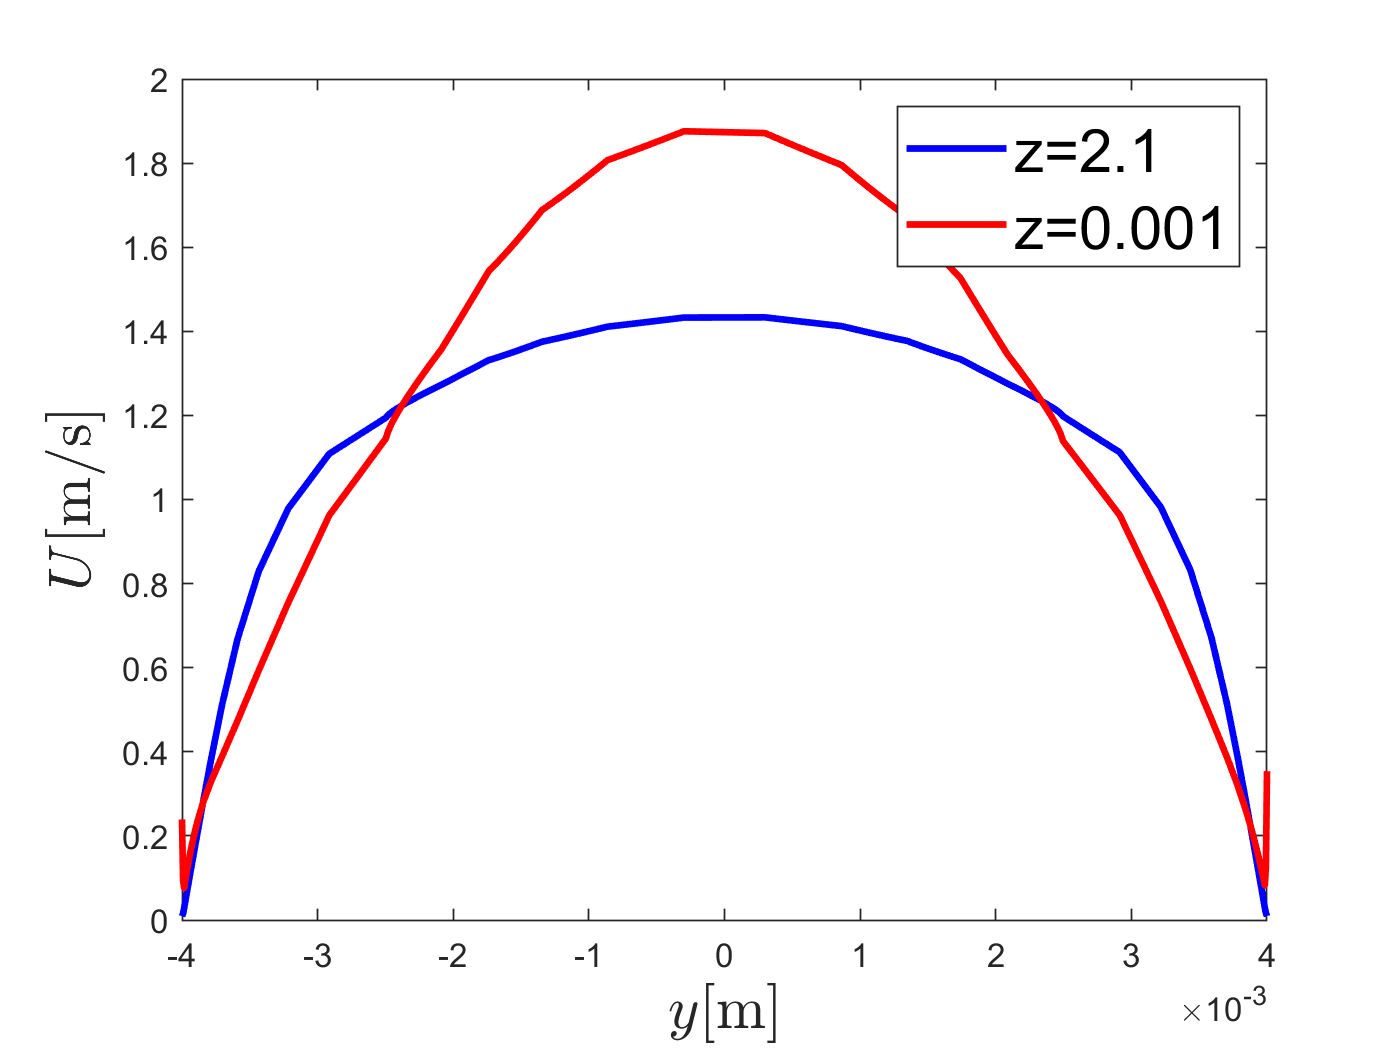

Path1="C:\Users\admin\Desktop\pipeflow\pipeflow_L2200D8_ds0.01_turbulent_SA";
[data,head,all]=xlsread(strcat(Path1,"\z=2.1.csv"));
[data1,title1,all1]=xlsread(strcat(Path1,"\z=0.001.csv"));
xyz=data(:,1:3);
Uxyz=data(:,5:7);
UMag=data(:,8);
xyz1=data1(:,1:3);
Uxyz1=data1(:,5:7);
UMag1=data1(:,8);

figure
plot(xyz(:,2),UMag,'-b','LineWidth',2);hold on;
plot(xyz1(:,2),UMag1,'-r','LineWidth',2);
% ti=title("Velocity Profile");
% ti.FontSize=18;
lg=legend("z=2.1","z=0.001");
lg.FontSize=18;
xlabel('$y$[m]','interpreter','latex', 'FontSize', 18);
ylabel('$U$[m/s]','interpreter','latex', 'FontSize', 18);

#### 压强数据%OpenFoam是单位密度的压强，Fluent是实际压强

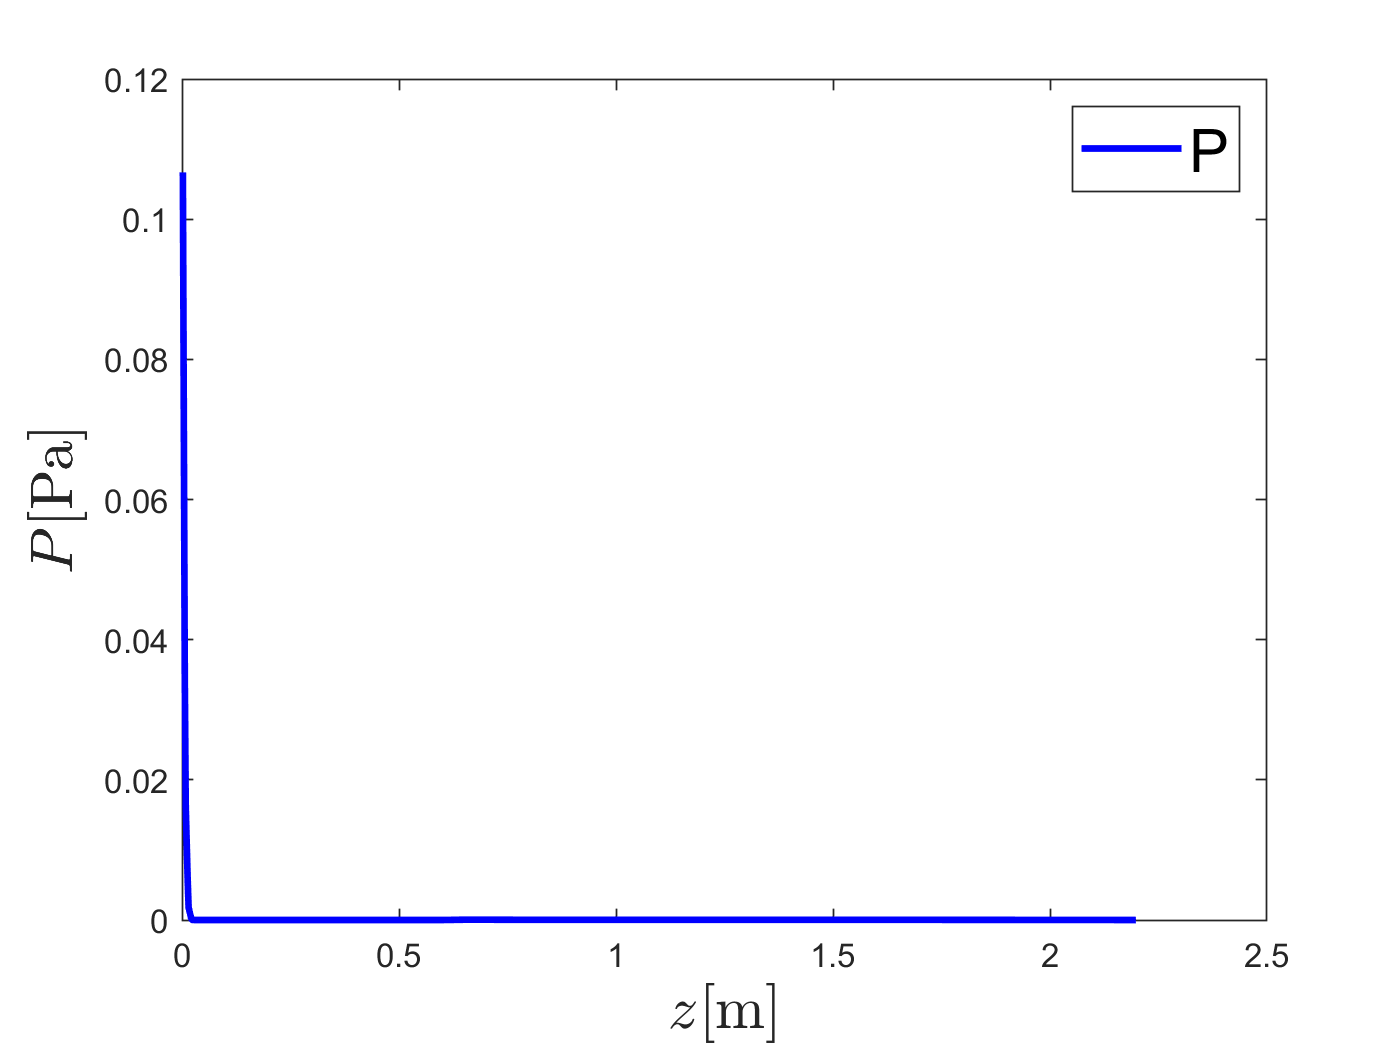

[data,head,all]=xlsread(strcat(Path1,"\xy=0.csv"));
figure
plot(data(2:end,3),data(2:end,10),'-b','LineWidth',2);
lg=legend("P");
lg.FontSize=18;
xlabel('$z$[m]','interpreter','latex', 'FontSize', 18);
ylabel('$P$[Pa]','interpreter','latex', 'FontSize', 18);

#### 根据压强计算摩擦因子

rho=1065;
Um=1;
L=1;
d=0.008;
mu=0.004;
nu=mu/rho;
Re=rho*Um*d/mu;
lambda=(data(365,10)-data(820,10))/(0.5*Um^2*L/d);
lambda1=64/Re;
lambda2=0.3164/(Re^(0.25));

#### 切应力

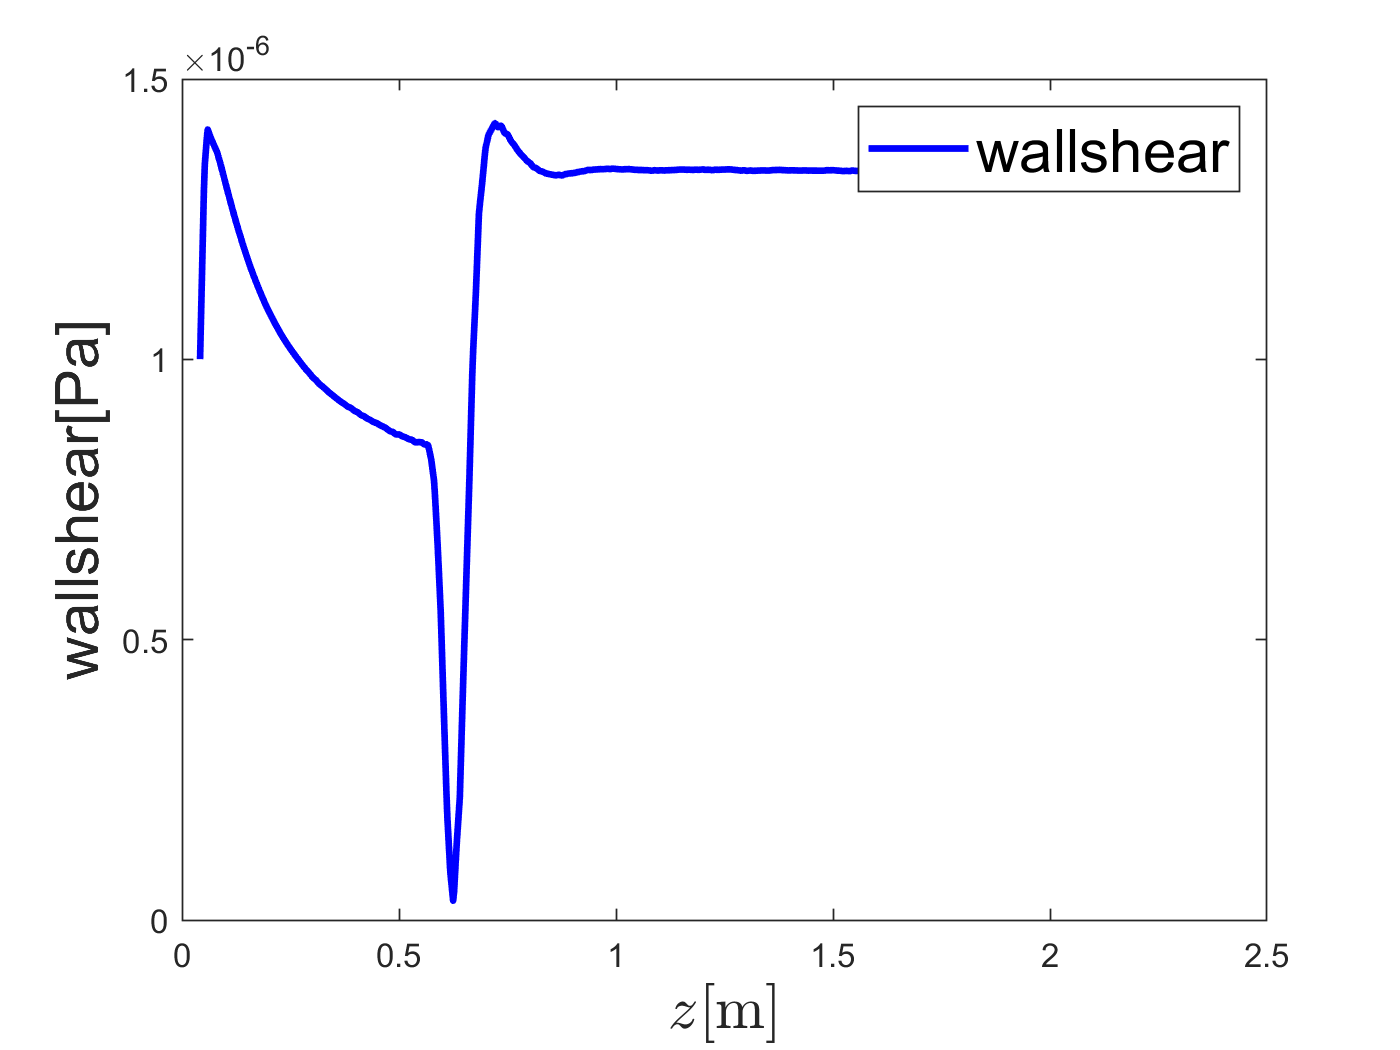

[data,head,all]=xlsread(strcat(Path1,"\y=-0.004.csv"));

figure
plot(data(20:end-20,3),data(20:end-20,16),'-b','LineWidth',2);hold on;
lg=legend("wallshear");
lg.FontSize=18;
xlabel('$z$[m]','interpreter','latex', 'FontSize', 18);
ylabel('wallshear[Pa]', 'FontSize', 18);

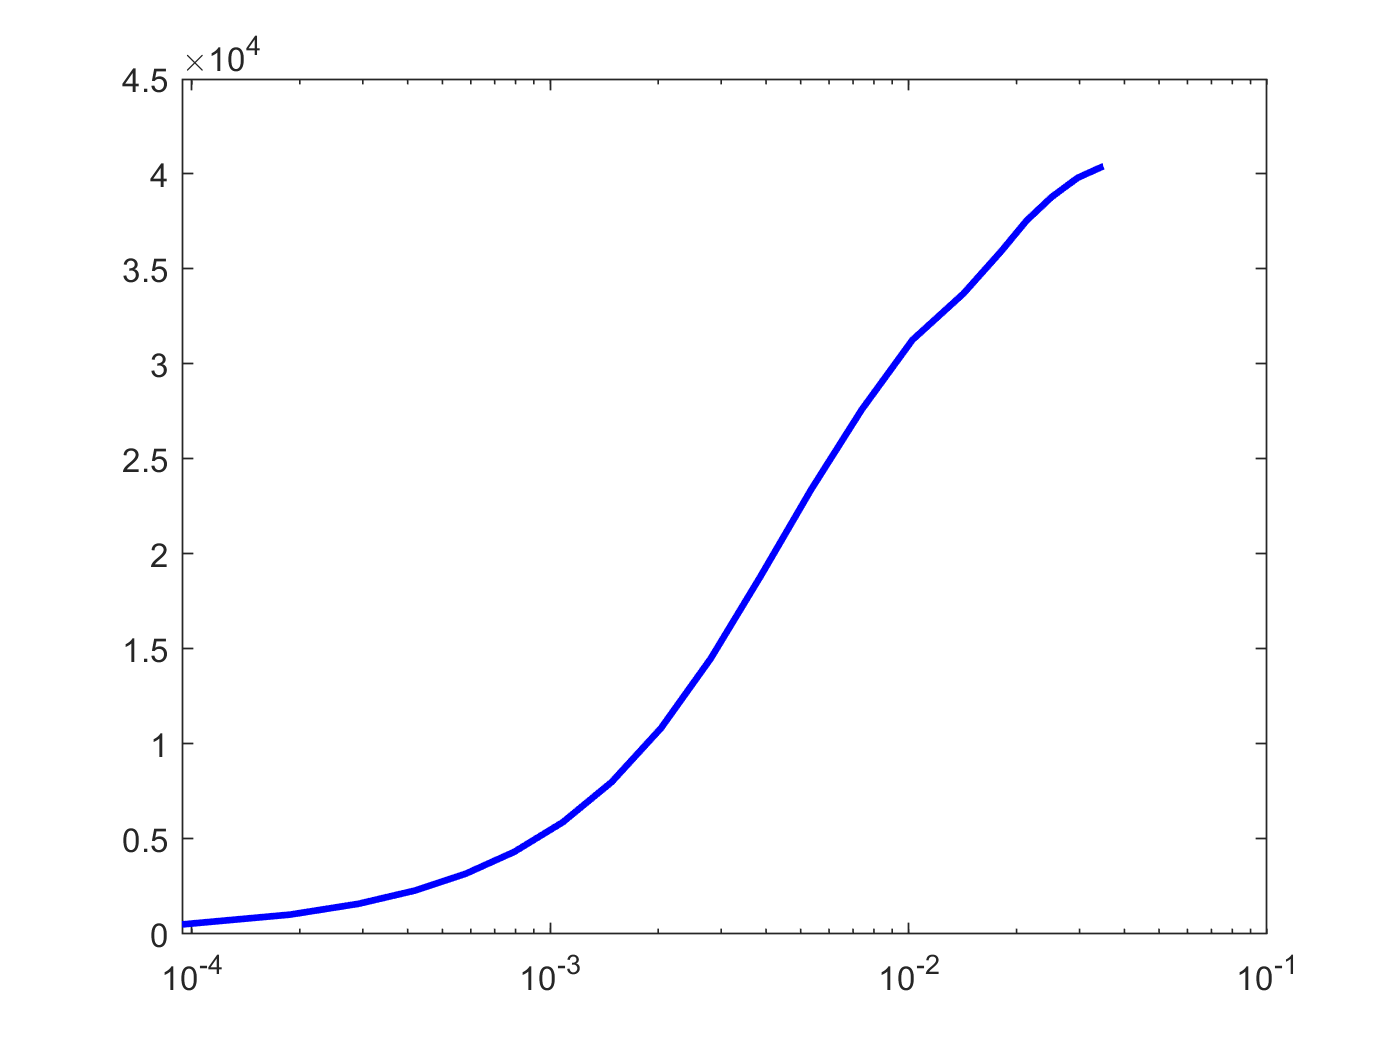


% figure
% yplus=uTao*(xyz(:,2)+0.004)/nu;
% uplus=Uxyz(:,2)/uTao;
% Ret=rho*uTao*d/mu;
% plot(yplus,uplus);

[data,head,all]=xlsread(strcat(Path1,"\slice.csv"));
ws=mean(data(111:246,15));%壁面切应力
uTao=sqrt(ws/rho);
for i=1:26
    uba(i)=mean(data(111+(i-1)*300:246+(i-1)*300,8));
    y(i)=data(i*300-1,2);
end
figure
yplus=uTao*(y(:)+0.004)/nu;
uplus=uba(:)/uTao;
semilogx(yplus,uplus,'-b','LineWidth',2);

## 输出数据